syms x;
f(x) = (x^2 + 1)^(-1);
inputs = linspace(-5, 5, 21);
outputs = zeros(21, 21);

for i = 1:21
    outputs(i, 1) = f(inputs(i));
end

for i = 1:20
    for j = 1:i
        outputs(i+1, j+1) = outputs(i+1, j) - outputs(i, j);
    end
end

s = (x-inputs(1)) / (inputs(2) - inputs(1));


syms P(x);

P(x) = outputs(1, 1);
for k = 1:20
    P(x) = P(x) + nchoosek(s, k) * outputs(k+1, k+1);
end

disp(P(x));

$$\frac{19\,x}{1105}+\frac{7\,\left({2\,x+10 \atop 2}\right)}{2210}+\frac{61826929060119\,\left({2\,x+10 \atop 3}\right)}{36028797018963968}+\frac{15\,\left({2\,x+10 \atop 4}\right)}{11713}+\frac{5608335690605\,\left({2\,x+10 \atop 5}\right)}{4503599627370496}+\frac{103861603938369\,\left({2\,x+10 \atop 6}\right)}{72057594037927936}+\frac{25392634786393\,\left({2\,x+10 \atop 7}\right)}{18014398509481984}-\frac{109589265920223\,\left({2\,x+10 \atop 8}\right)}{36028797018963968}-\frac{1323089917817733\,\left({2\,x+10 \atop 9}\right)}{36028797018963968}-\frac{210491577834615\,\left({2\,x+10 \atop 10}\right)}{9007199254740992}+\frac{3870038009616717\,\left({2\,x+10 \atop 11}\right)}{4503599627370496}-\frac{3919653881534891\,\left({2\,x+10 \atop 12}\right)}{1125899906842624}+\frac{7988155378824295\,\left({2\,x+10 \atop 13}\right)}{1125899906842624}-\frac{3473111034271553\,\left({2\,x+10 \atop 14}\right)}{1125899906842624}-\frac{5209666551407073\,\left({2\,x+10 \atop 15}\right)}{140737488355328}+\frac{6381841525473693\,\left({2\,x+10 \atop 16}\right)}{35184372088832}-\frac{2490871819891521\,\left({2\,x+10 \atop 17}\right)}{4398046511104}+\frac{196888765175249\,\left({2\,x+10 \atop 18}\right)}{137438953472}-\frac{6959788908520431\,\left({2\,x+10 \atop 19}\right)}{2199023255552}+\frac{6959788908520431\,\left({2\,x+10 \atop 20}\right)}{1099511627776}+\frac{55}{442}$$

% 단순화된 기호 표현식 구하기
simplifiedExpr = expand((19*x)/1105 + (7*nchoosek((2*x + 10), 2))/2210 + (sym("61826929060119")*nchoosek((2*x + 10), 3))/sym("36028797018963968") + (15*nchoosek((2*x + 10), 4))/11713 + (sym("5608335690605")*nchoosek((2*x + 10), 5))/sym("4503599627370496") + (sym("103861603938369")*nchoosek((2*x + 10), 6))/sym("72057594037927936") + (sym("25392634786393")*nchoosek((2*x + 10), 7))/sym("18014398509481984") - (sym("109589265920223")*nchoosek((2*x + 10), 8))/sym("36028797018963968") - (sym("1323089917817733")*nchoosek((2*x + 10), 9))/sym("36028797018963968") - (sym("210491577834615")*nchoosek((2*x + 10), 10))/sym("9007199254740992") + (sym("3870038009616717")*nchoosek((2*x + 10), 11))/sym("4503599627370496") - (sym("3919653881534891")*nchoosek((2*x + 10), 12))/sym("1125899906842624") + (sym("7988155378824295")*nchoosek((2*x + 10), 13))/sym("1125899906842624") - (sym("3473111034271553")*nchoosek((2*x + 10), 14))/sym("1125899906842624") - (sym("5209666551407073")*nchoosek((2*x + 10), 15))/sym("140737488355328") + (sym("6381841525473693")*nchoosek((2*x + 10), 16))/sym("35184372088832") - (sym("2490871819891521")*nchoosek((2*x + 10), 17))/sym("4398046511104") + (sym("196888765175249")*nchoosek((2*x + 10), 18))/sym("137438953472") - (sym("6959788908520431")*nchoosek((2*x + 10), 19))/sym("2199023255552") + (sym("6959788908520431")*nchoosek((2*x + 10), 20))/sym("1099511627776") + sym(55/442))

$$simplifiedExpr = \frac{2319929636173477\,x^{20}}{850360885375276154880000}-\frac{28498504056994187\,x^{18}}{107414006573719093248000}+\frac{1810033522454506651\,x^{16}}{168492559331324067840000}+\frac{x^{15}}{5616418644377468928000}-\frac{63733888414940482877\,x^{14}}{269588094930118508544000}-\frac{131\,x^{13}}{5135011332002257305600}+\frac{3859482806549638458527\,x^{12}}{1244252745831316193280000}+\frac{2231\,x^{11}}{7900017433849626624000}-\frac{520792908691169439361\,x^{10}}{20737545763855269888000}-\frac{45679\,x^{9}}{8043654114465074380800}+\frac{7261073375523432256725253\,x^{8}}{57512126918425281822720000}-\frac{228833\,x^{7}}{5745467224617910272000}-\frac{40542261623756174567365501\,x^{6}}{103521828453165507280896000}-\frac{55435109\,x^{5}}{202240446306550441574400}+\frac{624601869444050657726761684723\,x^{4}}{829094821656018862756331520000}-\frac{297132686423\,x^{3}}{541892040298051544285184000}-\frac{67613767953708419655075826841\,x^{2}}{70012451606508259521645772800}-\frac{10299651233\,x}{2924496725418055953285120}+\frac{1648458201105950831}{1648458201105956864}$$

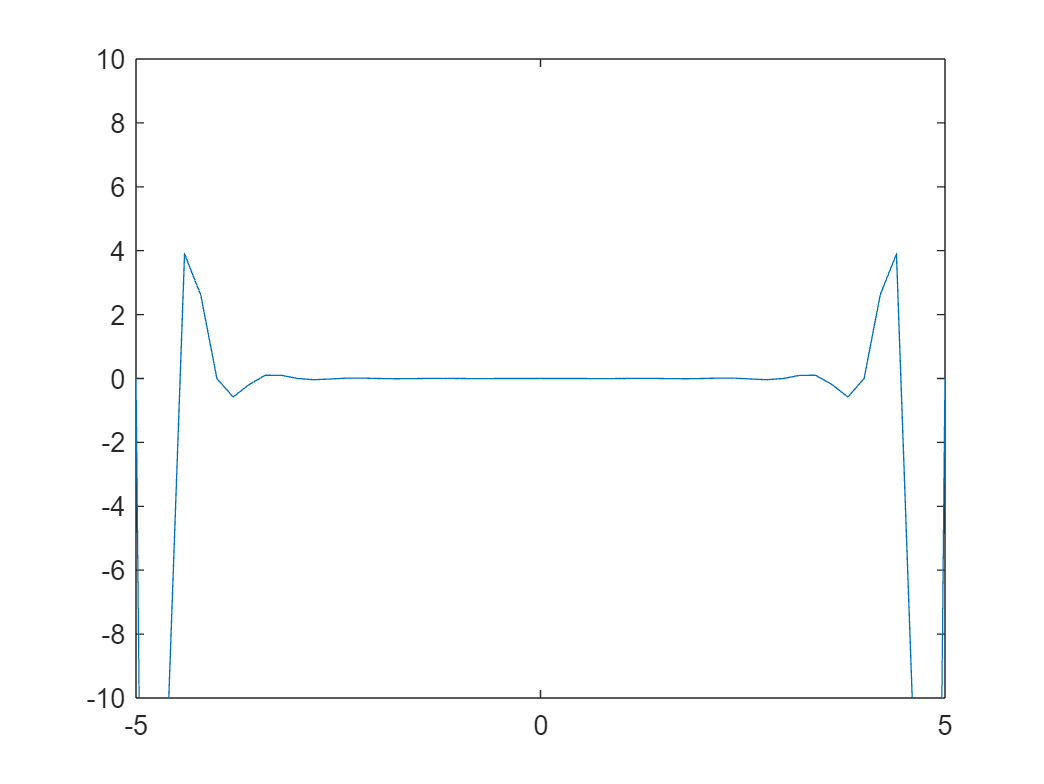


% Plot P(x)-f(x)
X = linspace(-5, 5, 51);
Y = zeros(1, 51);
for i = 1:51
    Y(i) = P(X(i)) - f(X(i));
end
plot(X, Y);
ylim([-10 10]);